# Setup

clear

% %Get paths to models
% mlxpath = DirectoryHandlerSweep;
% pathTemp = split(mlxpath,'\');
% pathTemp = join(pathTemp(1:size(pathTemp,1)-1),'\');
% 
% simPath = pathTemp + "\Reproduce Land‘s Model\CombinedModel.slx";
% diffPath = pathTemp + "\Reproduce Land‘s Model\combinedDiffEquation.m";

%Set up time span and vector
dt = 0.01; %s
tend = 20; %s
t = 0:dt:tend;



%Setup Simulink Parameters
open_system('CombinedModel.slx')
set_param('CombinedModel','StartTime','0','StopTime',num2str(tend),'FixedStep',num2str(dt),'FastRestart','on')
save_system('CombinedModel.slx')

# Sweep 1: PSM only and Input Frequency

## Constant simulation values

%Constant Gains
PSM = 0; %Just for crafting the sim_Set
VSM = 0;
PSA = 0;
VSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

## Simple sweep over small PSM, frequency range

% PSM_Range = 1:2:21;
% freq_range = 1:1:5;

## Sweep Function Call + plot full sweep grid

% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_FullSweep(sweep_Results,PSM_Range,freq_range,"PSM")

As can be seen, the stability seems to be independent of input frequency (at least for the range chosen above).  We can more closely investigate the stability with

respect to the gain by sweeping only across the gain.

## Sweep across PSM gain only (frequency 1 Hz)

% PSM_Range = 1:0.5:20;
% freq_range = 1;

## Sweep Function Call + plot sweep grid

% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

From this we can see that for an input frequency of 1 Hz, instability occurs with a PSM somewhere between 15 and 16.  Let's more closely examine that interval.

## Sweep across PSM gain only: 15-16 (frequency 1 Hz)

% PSM_Range = 15:0.05:16;
% freq_range = 1;

## Sweep Function Call + plot sweep grid

% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

Looks like we need to increase the simulation time to get a clearer picture...

## Increase simulation time

% %Set up time span and vector
% dt = 0.01; %s
% tend = 400; %s
% t = 0:dt:tend;
% 
% set_param('CombinedModel','StartTime','0','StopTime',num2str(tend),'FixedStep',num2str(dt),'FastRestart','on')
% save_system('CombinedModel.slx')

## Sweep across PSM gain only: 15-16 (frequency 1 Hz, tend = 400s)

% PSM_Range = 15:0.05:16;
% freq_range = 1;

## Sweep Function Call + plot sweep grid

% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

We can see that instability has an onset somewhere between PSM=15.7 and PSM=15.75.  Let's ensure that this is true at other frequencies as well.

## Sweep across PSM gain only: 15.7-15.75 (frequency 2-5 Hz, tend = 400s), plots

% PSM_Range = [15.7 15.75];
% freq_range = 2;
% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")
% 
% freq_range = 3;
% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")
% 
% freq_range = 4;
% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")
% 
% freq_range = 5;
% sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
% plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

We can see that the onset of instability occurs at the same location, regardless of input signal frequency.

Let's take a look at this in another way:

## Large Sweep with binary plot

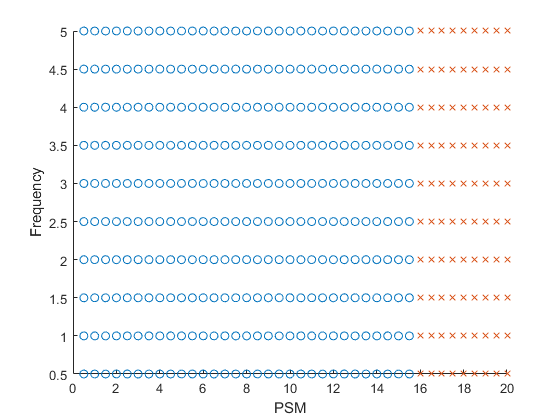

%Set up time span and vector
dt = 0.01; %s
tend = 100; %s
t = 0:dt:tend;

set_param('CombinedModel','StartTime','0','StopTime',num2str(tend),'FixedStep',num2str(dt),'FastRestart','on')
save_system('CombinedModel.slx')

%Ranges
PSM_Range = 0.5:.5:20;
freq_range = 0.5:.5:5;

%Simulate
sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
[unstable,stable] = stabChecker(sweep_Results,PSM_Range,freq_range);

%Binary Plot
%Create Stable and Unstable series'
unstableBinary = unstable(:,1:2);
stableBinary = stable(:,1:2);

figure
scatter(stableBinary(:,1), stableBinary(:,2),'o')
hold on
scatter(unstableBinary(:,1), unstableBinary(:,2),'x')
xlabel('PSM')
ylabel('Frequency')

# Sweep 2: VSM only and Input Frequency

## Constant simulation values

%Constant Gains
PSM = 0; 
VSM = 0; %Just for crafting the sim_Set
PSA = 0;
VSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'divisor',divisor,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

## Simple sweep over small VSM, frequency range

% VSM_Range = 1:2:21;
% freq_range = 1:1:5;

## Sweep Function Call + plot full sweep grid

% sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
% plot_FullSweep(sweep_Results,VSM_Range,freq_range,"VSM")

As can be seen, the break to instability occurs at much lower levels than PSM.  Let's adjust the range of gains.

## Sweep across VSM at lower gains

% VSM_Range = 0:.2:2;
% freq_range = 1:1:5;

## Sweep Function Call + plot sweep grid

% sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
% plot_FullSweep(sweep_Results,VSM_Range,freq_range,"VSM")

## Large Sweep with binary plot

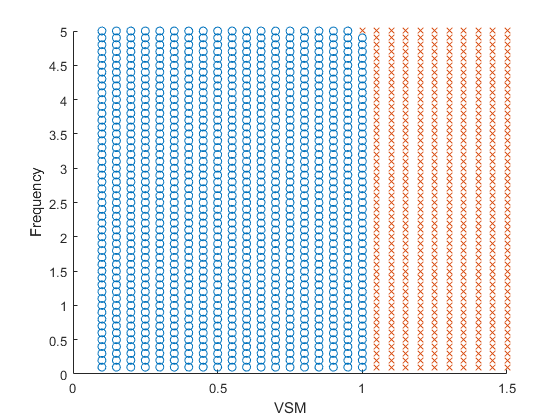

%Ranges
VSM_Range = 0.1:.05:1.5;
freq_range = 0.1:.1:5;

%Simulate
sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
[unstable,stable] = stabChecker(sweep_Results,VSM_Range,freq_range);

%Binary Plot
%Create Stable and Unstable series'
unstableBinary = unstable(:,1:2);
stableBinary = stable(:,1:2);

figure
scatter(stableBinary(:,1), stableBinary(:,2),'o')
hold on
scatter(unstableBinary(:,1), unstableBinary(:,2),'x')
xlabel('VSM')
ylabel('Frequency')

% %Ranges
% VSM_Range = [1 1.05];
% freq_range = [4.9 5.0];
% 
% %Simulate
% sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
% plot_FullSweep(sweep_Results,VSM_Range,freq_range,"VSM")

# Sweep 4: PSA only and Input Frequency

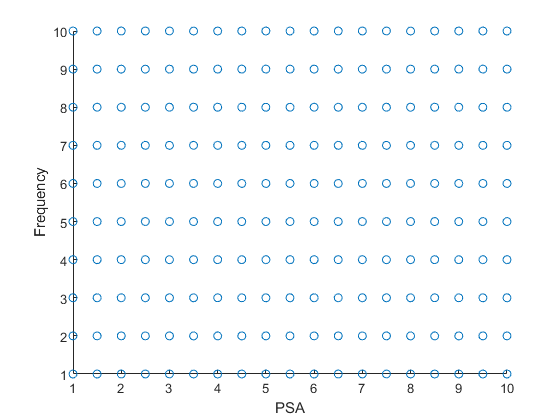

%Constant Gains
PSM = 0; 
VSM = 0; 
PSA = 0;%Just for crafting the sim_Set
VSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'divisor',divisor,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

%Ranges
PSA_Range = 1:.5:10;
freq_range = 1:1:10;

%Simulate
sweep_Results = GainFreq2ParamSweep("PSA",PSA_Range,freq_range,t,dt,sim_Set);
[unstable,stable] = stabChecker(sweep_Results,PSA_Range,freq_range);

%Binary Plot
%Create Stable and Unstable series'

if isempty(unstable)
    stableBinary = stable(:,1:2);
    figure
    scatter(stableBinary(:,1), stableBinary(:,2),'o')
    xlabel('PSA')
    ylabel('Frequency')
elseif isempty(stable)
    unstableBinary = unstable(:,1:2);
    figure
    scatter(unstableBinary(:,1), unstableBinary(:,2),'x')
    xlabel('PSA')
    ylabel('Frequency')
else
   unstableBinary = unstable(:,1:2);
    stableBinary = stable(:,1:2);

    figure
    scatter(stableBinary(:,1), stableBinary(:,2),'o')
    hold on
    scatter(unstableBinary(:,1), unstableBinary(:,2),'x')
    xlabel('PSA')
    ylabel('Frequency')
end

# Sweep 3: VSA only and Input Frequency

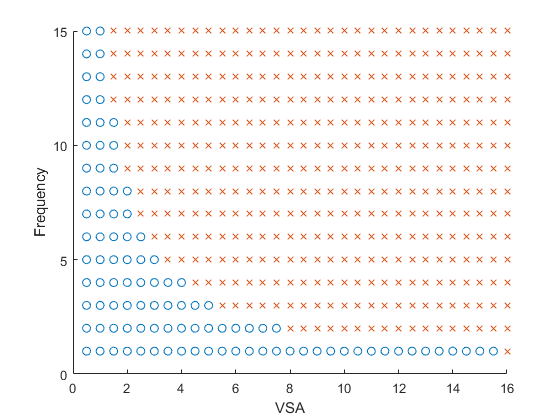

%Constant Gains
PSM = 0; 
VSM = 0; 
PSA = 1;
VSA = 0;%Just for crafting the sim_Set

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'divisor',divisor,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

%Ranges
VSA_Range = 0.5:.5:16;
freq_range = 1:1:15;

%Simulate
sweep_Results = GainFreq2ParamSweep("VSA",VSA_Range,freq_range,t,dt,sim_Set);
[unstable,stable] = stabChecker(sweep_Results,VSA_Range,freq_range);

%Binary Plot
%Create Stable and Unstable series'

if isempty(unstable)
    stableBinary = stable(:,1:2);
    figure
    scatter(stableBinary(:,1), stableBinary(:,2),'o')
    xlabel('VSA')
    ylabel('Frequency')
elseif isempty(stable)
    unstableBinary = unstable(:,1:2);
    figure
    scatter(unstableBinary(:,1), unstableBinary(:,2),'x')
    xlabel('VSA')
    ylabel('Frequency')
else
   unstableBinary = unstable(:,1:2);
    stableBinary = stable(:,1:2);

    figure
    scatter(stableBinary(:,1), stableBinary(:,2),'o')
    hold on
    scatter(unstableBinary(:,1), unstableBinary(:,2),'x') 
    xlabel('VSA')
    ylabel('Frequency')
end

# Smooth System Sweep - constant delay

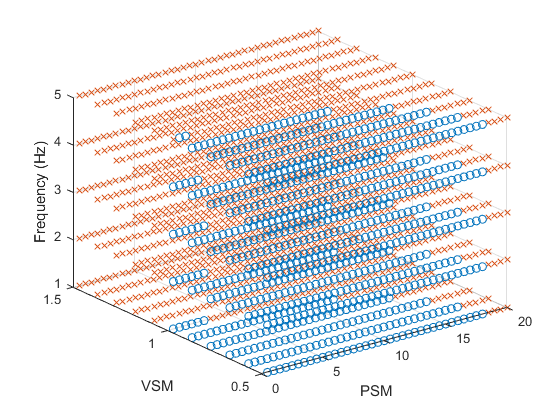

%Constant Gains
PSM = 0; 
VSM = 0; 
PSA = 0;
VSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'divisor',divisor,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

%Ranges
PSM_Range = 0.5:.5:20;
VSM_Range = 0.5:.1:1.5;
freq_range = 1:1:5;

%Simulate
sweep_Results = GainFreq3ParamSweep("PSM",PSM_Range,"VSM",VSM_Range,freq_range,t,dt,sim_Set);
[unstable,stable] = stabChecker2Gain(sweep_Results,PSM_Range,VSM_Range,freq_range);

%Binary Plot
%Create Stable and Unstable series'

if isempty(unstable)
    figure
    scatter3(stable(:,1), stable(:,2), stable(:,3),'o')
    xlabel('PSM')
    ylabel('VSM')
    zlabel('Frequency (Hz)')
elseif isempty(stable)
    figure
    scatter3(unstable(:,1), unstable(:,2), unstable(:,3),'x')
    xlabel('PSM')
    ylabel('VSM')
    zlabel('Frequency (Hz)')
else
    figure
    scatter3(stable(:,1), stable(:,2), stable(:,3),'o')
    hold on
    scatter3(unstable(:,1), unstable(:,2), unstable(:,3),'x')
    xlabel('PSM')
    ylabel('VSM')
    zlabel('Frequency (Hz)')
end

# Smooth System Sweep - constant frequency

%Constant Gains
PSM = 0; 
VSM = 0; 
PSA = 0;
VSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'divisor',divisor,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

%Ranges
PSM_Range = 0.5:.5:20;
VSM_Range = 0.5:.1:1.2;
delay_Range = 0.05:0.01:0.5

delay_Range =     0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


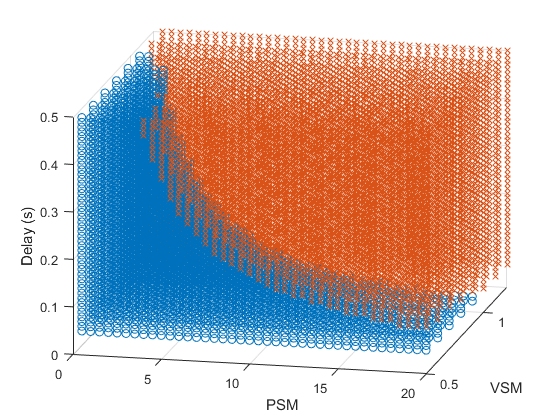

freq = 3;

%Simulate
sweep_Results = GainDelay3ParamSweep("PSM",PSM_Range,"VSM",VSM_Range,delay_Range,freq,t,dt,sim_Set);
[unstable,stable] = stabChecker2GainDelay(sweep_Results,PSM_Range,VSM_Range,delay_Range);

%Binary Plot
%Create Stable and Unstable series'

if isempty(unstable)
    figure
    scatter3(stable(:,1), stable(:,2), stable(:,3),'o')
    xlabel('PSM')
    ylabel('VSM')
    zlabel('Delay (s)')
elseif isempty(stable)
    figure
    scatter3(unstable(:,1), unstable(:,2), unstable(:,3),'x')
    xlabel('PSM')
    ylabel('VSM')
    zlabel('Delay (s)')
else
    figure
    scatter3(stable(:,1), stable(:,2), stable(:,3),'o')
    hold on
    scatter3(unstable(:,1), unstable(:,2), unstable(:,3),'x')
    xlabel('PSM')
    ylabel('VSM')
    zlabel('Delay (s)')
end